# Adaptive Chaotic Modulation for SatCom 

**Written by: Seoyoon Jung (****sj4260@nyu.edu****)**

ECE-UY-3404 Fundamentals of Communication Theory

Spring 2026 Prof. Unnikrishna Pillai

clc;clear;close all;  

## **Simulation Setup**

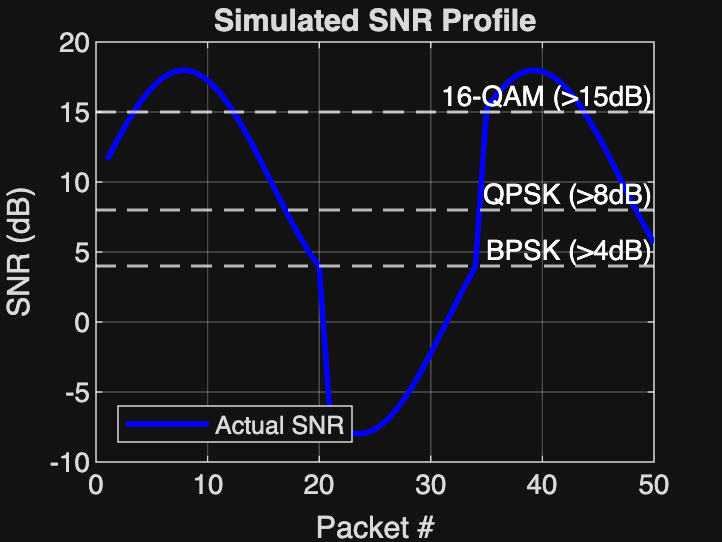

nPackets = 50;
bitsPerPacket = 1000; % number of symbols
nov = 8; % symbol resolution (samples per symbol)
targetBER = 1e-3; % policy
a = 2.3; % chaos parameter (>2)
sir_dB = 10; % interference strength (10dB below signal power)

time = 1:nPackets;

% Dynamic SNR
snr_profile = 10 + 8*sin(0.2*time) - (time > 20 & time < 35)*10; 
% visualize: clear sky -> deep fade -> recovery
figure;
plot(time, snr_profile, 'b', 'LineWidth', 2);
yline(15, 'w--', '16-QAM (>15dB)', 'LineWidth', 1);
yline(8,  'w--', 'QPSK (>8dB)', 'LineWidth', 1);
yline(4,  'w--', 'BPSK (>4dB)', 'LineWidth', 1); 
grid on; ylabel('SNR (dB)'); xlabel('Packet #'); title('Simulated SNR Profile');
legend('Actual SNR', 'Location', 'southwest');



% Channel environments
channel_modes = {'awgn', 'awgn+interference'};

## Pipeline overview

1) **Input**: Signal / Image+Llyod-Max (i.e. Start Tracker data)

2) **Channel**:  AWGN / AWGN+interference

3) Linear **SNR esimator**

4) **ACM transceiver**: linear (QAM/QPSK/BPSK) / chaotic (CSK)

--> Performance metrics: BER vs SNR, BER vs Throughput, Reconstructed image, RMSE comparison table 

(Supporting functions:)

- `adaptive_controller.m`

- `mod_qam.m`: (M: 2= BPSK, 4= QPSK, 16= 16QAM)

- `mod_csk.m`: CSK

## Adaptive Coding and Modulation (ACM)

1) Estimator

- Predicts next SNR

- `trend`: based on slope of SNR. switch to CSK if signal strength fades into noise

- Robust against scintillation (high-freq ionospheric disturbance)

2) Adaptive controller

% [16-QAM] <---- [QPSK] <---- [BPSK] <---- [CSK]
% (Fast; Need high SNR)        (Robust; Latency)

- switches` mod scheme based on environment

- `targetBER`: determines controller behavior for tradeoff

- tradeoff between speed (throughput) and reliability (SNR resilience)

- sampling frequency must stay the same 

-     QAM/BPSK: length(tx_sig) = bitsPerPacket / log2(M) * nov

-     CSK: length(tx_sig) = bitsPerPacket * nov

- assumption: controller has interference detector (if channel == AWGN or AWGN+inteference)

### A) Signal Input:

fprintf('\n=== INPUT: SIGNAL ===\n');


=== INPUT: SIGNAL ===


results_signal = cell(1,2);

for ch = 1:2
    channel_mode = channel_modes{ch};
    fprintf('Channel: %s\n', channel_mode);
    results_signal{ch} = struct('mode',{},'ber',{},'throughput',{},'snr',{});

    for t = 1:nPackets
        bits = randi([0 1], 1, bitsPerPacket); % TX: random bits
        currentSNR = snr_profile(t);

        % SNR estimator
        if t > 1
            trend = currentSNR - snr_profile(t-1); % slope
            predictedSNR = currentSNR + trend; % extrapolate
        else
            predictedSNR = currentSNR;
        end
        predictedSNR = max(predictedSNR, 0); % clamp to positive

        % Adaptive controller
        [ber, mode, bitsPerSym] = adaptive_controller( ...
            bits, currentSNR, predictedSNR, nov, a, channel_mode, sir_dB);

        results_signal{ch}(t).mode = mode;
        results_signal{ch}(t).ber = ber;
        results_signal{ch}(t).snr = currentSNR;
        results_signal{ch}(t).predicted_snr = predictedSNR;
        results_signal{ch}(t).throughput = bitsPerSym * (1 - ber);
    end
end

Channel: awgn
Channel: awgn+interference


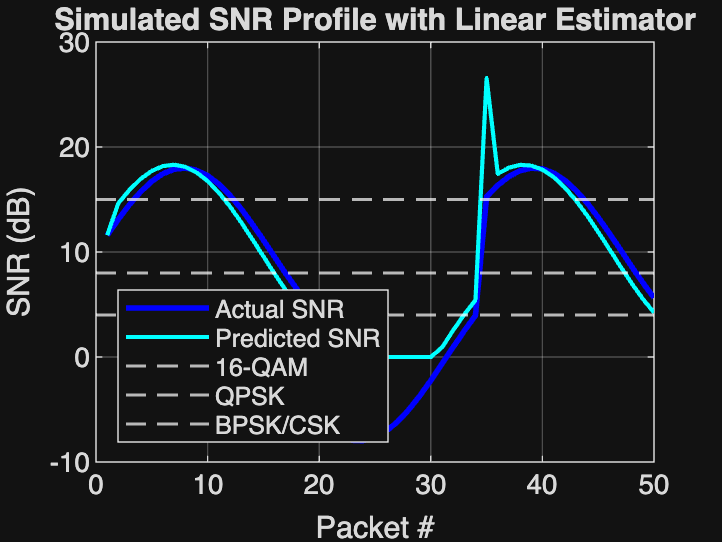


% plot SNR estimator performance
figure;
plot(time, [results_signal{1}.snr], 'b', 'LineWidth', 2); hold on; % actual SNR profile
plot(time, [results_signal{1}.predicted_snr], 'c', 'LineWidth', 1.5); % estimated SNR
yline(15, 'w--', 'LineWidth', 1);
yline(8,  'w--', 'LineWidth', 1);
yline(4,  'w--', 'LineWidth', 1); grid on;
ylabel('SNR (dB)'); xlabel('Packet #');
title('Simulated SNR Profile with Linear Estimator');
legend('Actual SNR', 'Predicted SNR', '16-QAM', 'QPSK', 'BPSK/CSK', ...
      'Location', 'southwest');

### B) Image Input:

fprintf('\n=== INPUT: IMAGE ===\n');


=== INPUT: IMAGE ===


### **Image compression**

(Adapted from Lab 6)

% Load image
img = imread('cameraman.tif');

if ndims(img) == 3, img = rgb2gray(img); end
img = double(img);
[rows, cols] = size(img); % store dim for reconstruction

### Lloyd-Max Quantization

K = 8; % numebr of quantization level
levels = linspace(0,255,K);

for iter = 1:20
    b = (levels(1:end-1) + levels(2:end))/2; % decision boundaries: level midpoints
    q_lloyd = zeros(size(img));

    for i = 1:K % assign each pixel to bin
        if     i == 1, mask = img <= b(i);
        elseif i == K, mask = img > b(i-1);
        else,          mask = img > b(i-1) & img <= b(i);
        end

        if any(mask(:)) 
            levels(i) = mean(img(mask)); % mean update for min.MSE within bin
        end

        q_lloyd(mask) = levels(i); % replace the bin with level value
    end
end
% MSE of quantization
mse_lloyd = mean((q_lloyd(:) - img(:)).^2);

% n.b. [ 143 -> quantize -> 140 -> index -> 4 -> encode -> 011 -> transmit ->
% 011 -> decode -> 4 -> lookup -> 140 ]

% Serialize each pixel
bitsPerPixel = ceil(log2(K)); % e.g. 1pixel=3bits
[~, pix_idx] = min(abs(levels' - img(:)'), [], 1); % pixel -> find closest level (idx)
pix_idx = pix_idx - 1; % 0-based
img_bits       = de2bi(pix_idx, bitsPerPixel, 'left-msb');
img_bits       = img_bits(:)'; 
results_image = cell(1,2); % TX: flat bit stream

% Pad bit length for later reconstruction
padTotal = ceil(length(img_bits) / lcm(bitsPerPacket, bitsPerPixel)) * lcm(bitsPerPacket, bitsPerPixel);
img_bits = [img_bits, zeros(1, padTotal - length(img_bits))];

nImgPackets = floor(length(img_bits) / bitsPerPacket); % how many full packets fit

% Transmission by packet
for ch = 1:2
    channel_mode = channel_modes{ch};
    rx_bits_all  = zeros(1, nImgPackets * bitsPerPacket);  % pre-allocate

    for t = 1:nImgPackets
        idx = (t-1)*bitsPerPacket + (1:bitsPerPacket);  % bit index for this packet
        bits = img_bits(idx);                           % slice of image bit stream
        currentSNR = snr_profile(mod(t-1, nPackets) + 1); % cycle SNR profile if image > 50 packets
       
        % SNR estimator
        if t > 1
            prev_snr     = snr_profile(mod(t-2, nPackets) + 1);
            predictedSNR = currentSNR + (currentSNR - prev_snr);
        else
            predictedSNR = currentSNR;
        end
        predictedSNR = max(predictedSNR, 0);
           
        % Adaptive controller
        [ber, mode, bitsPerSym, rx_bits] = adaptive_controller( ...
            bits, currentSNR, predictedSNR, nov, a, channel_mode, sir_dB);

        rx_bits_all(idx)          = rx_bits;
        results_image{ch}(t).mode = mode;
        results_image{ch}(t).ber  = ber;
        results_image{ch}(t).snr  = currentSNR;
        results_image{ch}(t).throughput = bitsPerSym * (1 - ber);

    end

    % Reconstruct image from received bits
    rx_matrix  = reshape(rx_bits_all, [], bitsPerPixel);     % group into 3-bit words
    rx_indices = bi2de(rx_matrix, 'left-msb') + 1;           % decode index (1-based)
    rx_indices = min(max(rx_indices, 1), K);                 % clamp to valid range
    rx_pixels = levels(rx_indices);                          % map index -> intensity
    rx_img = reshape(rx_pixels(1:rows*cols), rows, cols); % back to 2D

    results_image{ch}(1).rmse = sqrt(mean((rx_img(:) - img(:)).^2));
    results_image{ch}(1).img  = rx_img;
end

## **Performance Analysis**

### **Per scheme: BER vs SNR characteristics (awgn)**

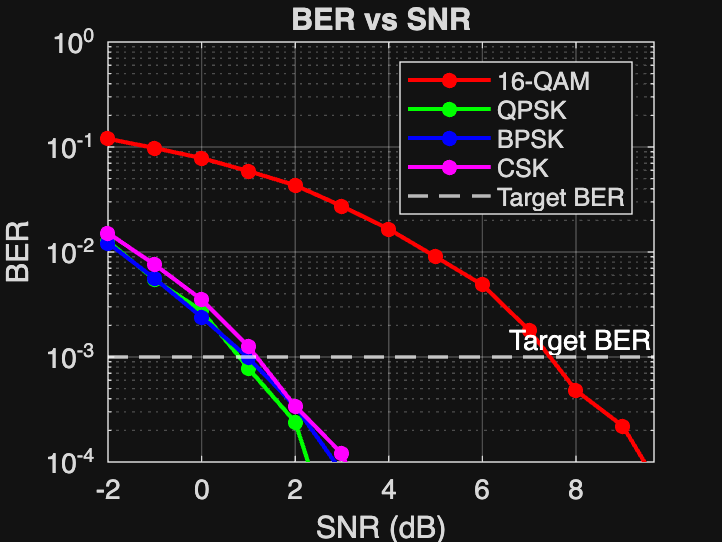

snr_range = -2:1:18; 
bits_test = randi([0 1], 1, 50000);
schemes_fixed = {'16-QAM', 'QPSK', 'BPSK', 'CSK'};
colors     = {'r','g','b','m'};

ber_curves = zeros(4, length(snr_range));

for si = 1:length(snr_range)
    snr = snr_range(si);
    
    % Per scheme
    [ber_curves(1,si),~] = mod_qam(bits_test, snr, 16, nov, 'awgn', Inf);
    [ber_curves(2,si),~] = mod_qam(bits_test, snr,  4, nov, 'awgn', Inf);
    [ber_curves(3,si),~] = mod_qam(bits_test, snr,  2, nov, 'awgn', Inf);
    [ber_curves(4,si),~] = mod_csk(bits_test, snr,  nov, a, 'awgn', Inf);
end

% plot per scheme
figure;
plot_data = max(ber_curves, 1e-5);
for si = 1:4
    semilogy(snr_range, plot_data(si,:), [colors{si} '-o'], ...
             'LineWidth', 1.5, 'MarkerSize', 4, 'MarkerFaceColor', colors{si}); hold on;
end
yline(targetBER, 'w--', 'Target BER', 'LineWidth', 1.2);
xlabel('SNR (dB)'); ylabel('BER');
title('BER vs SNR');
legend('16-QAM','QPSK','BPSK','CSK','Target BER', 'Location','northeast');
grid on; ylim([1e-4 1]);

### **Per scheme: Image reconstruction at low SNR**

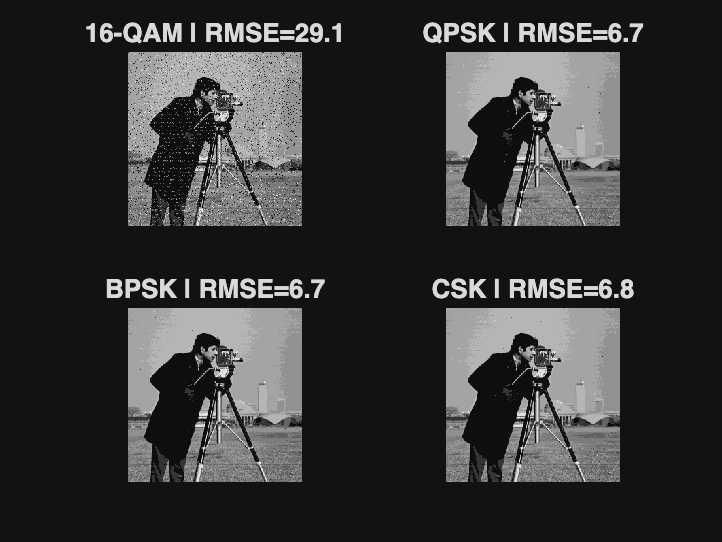

testSNR = 2; 
forced_results = cell(1,4);
schemes_to_test = {'16-QAM', 'QPSK', 'BPSK', 'CSK'};
nBitsNeeded = rows * cols * bitsPerPixel;

for s = 1:4    
    if s < 4
        M_val = [16, 4, 2];
        [~, rx_bits_force] = mod_qam(img_bits(1:nBitsNeeded), testSNR, M_val(s), nov, 'awgn', Inf);
    else
        [~, rx_bits_force] = mod_csk(img_bits(1:nBitsNeeded), testSNR, nov, a, 'awgn', Inf);
    end
    
    % Reconstruct
    rx_m_f = reshape(rx_bits_force(1:nBitsNeeded), [], bitsPerPixel);
    rx_id_f = min(max(bi2de(rx_m_f, 'left-msb') + 1, 1), K);
    forced_results{s} = reshape(levels(rx_id_f), rows, cols);
end

% Plotting
figure;
for s = 1:4
    subplot(2,2,s);
    imshow(uint8(forced_results{s}));
    rmse_s = sqrt(mean((double(forced_results{s}(:)) - img(:)).^2));
    title(sprintf('%s | RMSE=%.1f', schemes_to_test{s}, rmse_s));
end

### **Controller decision based on SNR**

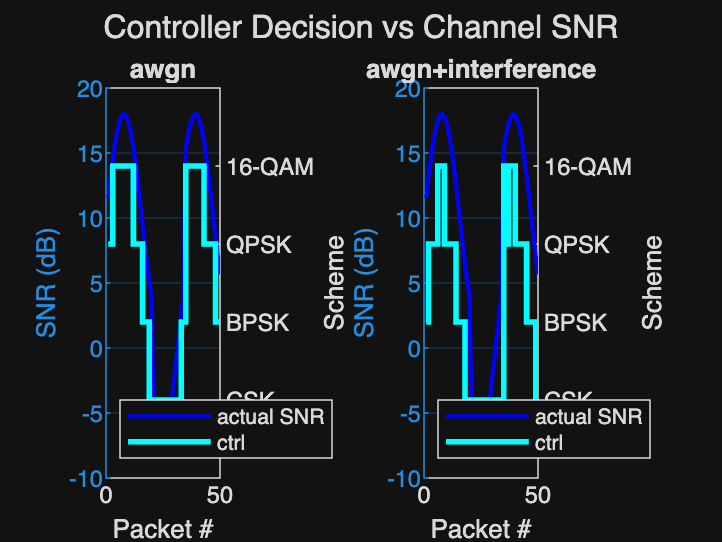

figure;
for ch = 1:2
    subplot(1,2,ch);
    
    % SNR on left axis
    yyaxis left;
    plot(time, [results_signal{ch}.snr], 'b', 'LineWidth', 1.5);
    ylabel('SNR (dB)');
    
    % modulation decision on right axis
    yyaxis right;
    cat_modes = categorical([results_signal{ch}.mode], {'CSK','BPSK','QPSK','16-QAM'});
    stairs(time, cat_modes, 'c', 'LineWidth', 2);
    ylabel('Scheme');
    legend('actual SNR','ctrl', 'Location','southwest');
    xlabel('Packet #'); title(channel_modes{ch}); grid on;
end
sgtitle('Controller Decision vs Channel SNR');

### **BER vs Throughput**

thr_curves = zeros(5, length(snr_range)); % 4 fixed schemes + 1 adaptive
m_vals = [log2(16), log2(4), log2(2), 1/nov]; % 16QAM(4), QPSK(2), BPSK(1), CSK(1/nov)
scheme_names = {'16-QAM', 'QPSK', 'BPSK', 'CSK'};
line_styles = {'r--', 'g--', 'b--', 'm--'};

% effective throughput
for si = 1:length(snr_range)
    snr = snr_range(si);
    % fixed schemes
    for i = 1:4
        thr_curves(i,si) = m_vals(i) * (1 - ber_curves(i,si));
    end
    % adaptive Selection
    if snr > 15, m_idx = 1;
    elseif snr > 8, m_idx = 2
    elseif snr > 4, m_idx = 3;
    else, m_idx = 4;
    end
    
    thr_curves(5,si) = m_vals(m_idx) * (1 - ber_curves(m_idx, si));
end

m_idx = 2

m_idx = 2

m_idx = 2

m_idx = 2

m_idx = 2

m_idx = 2

m_idx = 2

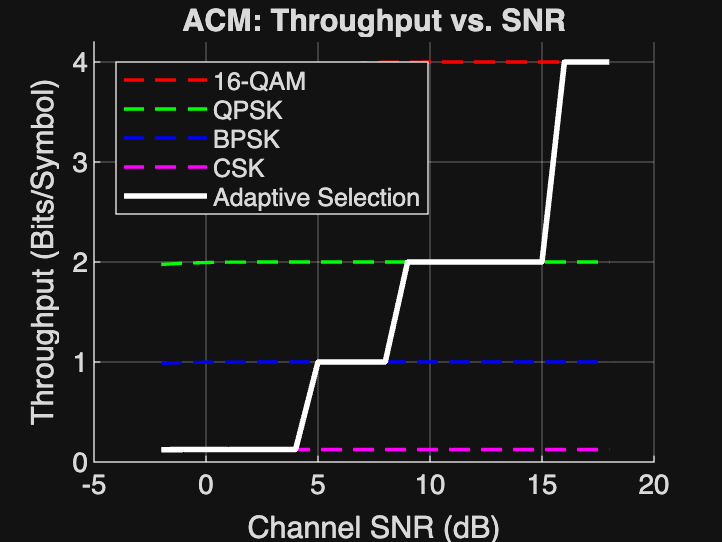


figure; hold on;
% fixed schemes
for i = 1:4
    plot(snr_range, thr_curves(i,:), line_styles{i}, 'LineWidth', 1.2);
end

% adaptive Controller
plot(snr_range, thr_curves(5,:), 'w-', 'LineWidth', 2); 

grid on;
xlabel('Channel SNR (dB)');
ylabel('Throughput (Bits/Symbol)');
title('ACM: Throughput vs. SNR');
legend([scheme_names, 'Adaptive Selection'], 'Location', 'northwest');
ylim([0 4.2]); % 16-QAM max is 4 bits/sym

### Image reconstruction

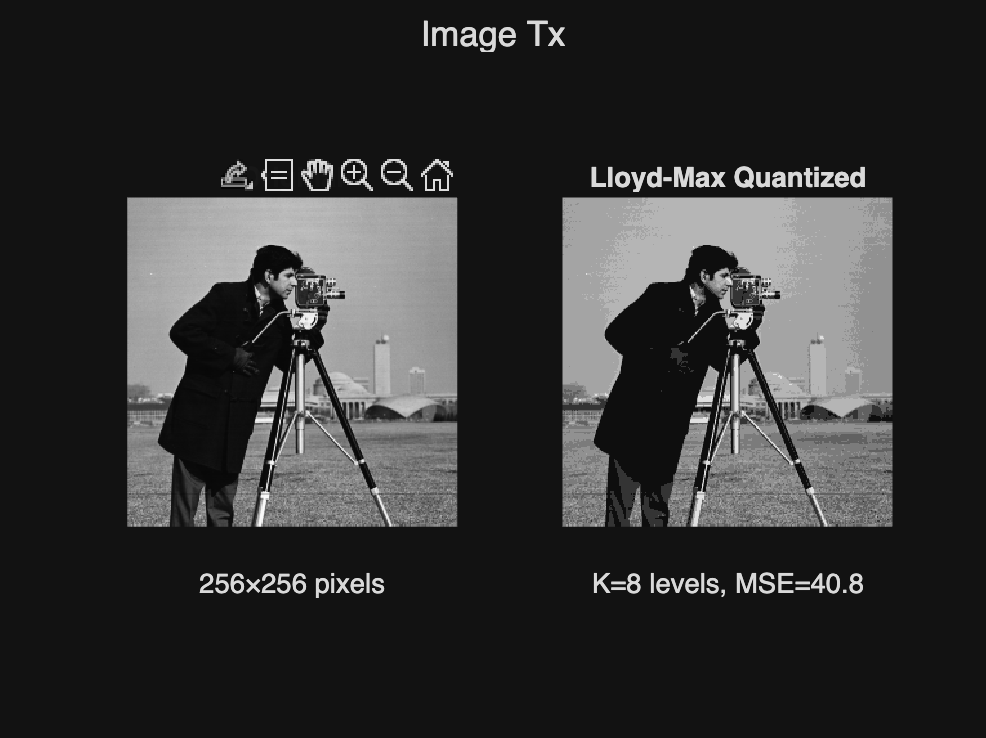

% TX
figure;
subplot(1,2,1); imshow(uint8(img));
title('Original'); xlabel(sprintf('%d×%d pixels', rows, cols));

subplot(1,2,2); imshow(uint8(q_lloyd));
title('Lloyd-Max Quantized'); xlabel(sprintf('K=%d levels, MSE=%.1f', K, mse_lloyd));

sgtitle('Image Tx');

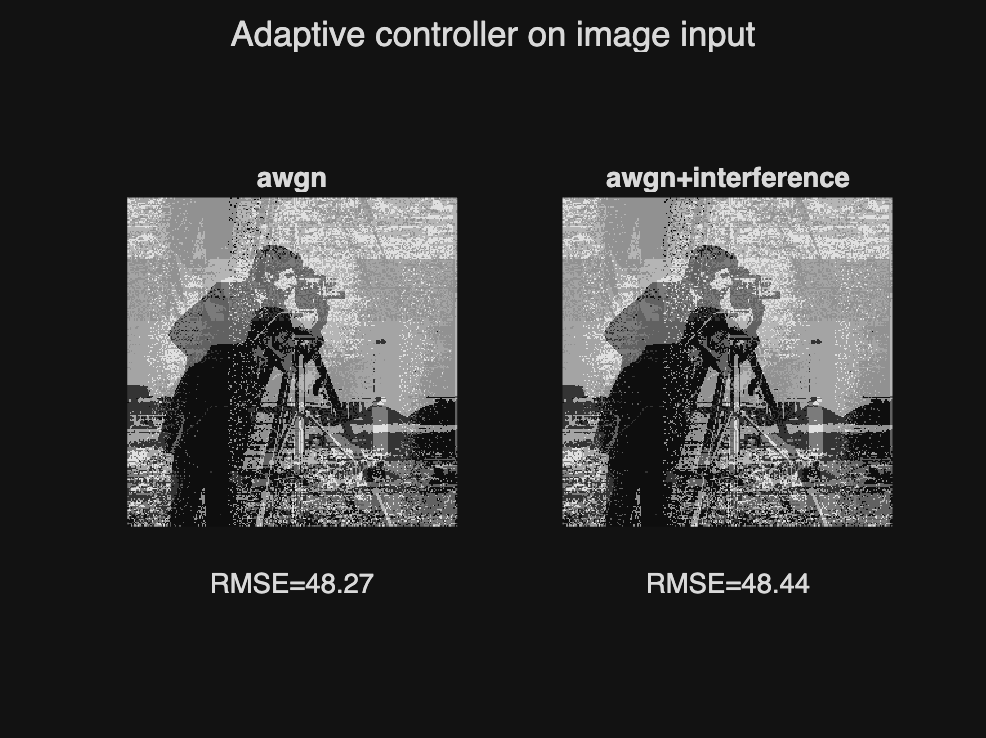


% RX- using controller
figure;
subplot(1,2,1); imshow(uint8(results_image{1}(1).img));
% plot(time, [results_image{1}.snr], 'r', 'LineWidth', 2);
title(sprintf('%s', channel_modes{1}));
xlabel(sprintf('RMSE=%.2f', results_image{1}(1).rmse));
subplot(1,2,2); imshow(uint8(results_image{2}(1).img));
title(sprintf('%s', channel_modes{2}));
xlabel(sprintf('RMSE=%.2f', results_image{2}(1).rmse));

sgtitle('Adaptive controller on image input');

## **n.b. CSK: parameter justification**

### **Chaotic map & Bifurcation Diagram**

(Adapted from Lab 6)

Using the nonlinear map: $$$x_{n+1} = a \cos(x_n)$$$

(commented out to save gpu rendering)

% % Bifurcation diagram
% a_list = 1.5:0.002:2.5;
% N = 800; burn = 400;
% A = []; X = [];
% 
% for a_val = a_list
%     x = 0.1;
%     for n = 1:N
%         x = a_val*cos(x);
%         if n > burn
%             A= [A, a_val];
%             X = [X, x];
%         end
%     end
% end
% 
% figure;
% plot(A, X, '.b', 'MarkerSize', 2);
% xlabel('a'); ylabel('x_n');
% title('Bifurcation Diagram');
% xline(2.3, 'r--', 'a = 2.3', 'LineWidth', 1.5);
% grid on;

### **Lyapunov Exponent (LLE)**

LLE measures sensitivity to initial conditions:


$$ $$\lambda = \frac{1}{N} \sum \log |f''(x_n)|$$

where for $f(x)=a\cos(x)$$$


A positive LLE means sensitive dependence on initial conditions, meaning the system is chaotic. LLE becomes positive for a>2. 

(commented out to save gpu rendering)

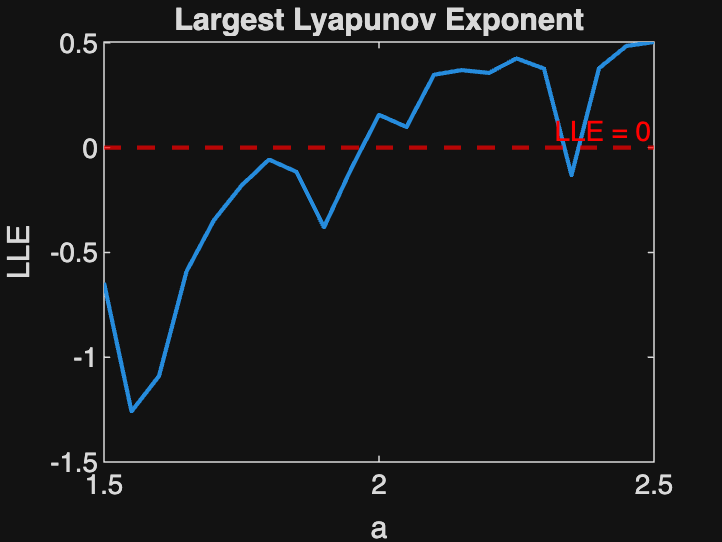

% a_list = 1.5:0.05:2.5;
% LLE = zeros(size(a_list));
% 
% for i = 1:length(a_list)
%     a_val = a_list(i);
%     x_temp = 0.1; sum_log = 0;
% 
%     for n = 1:3000
%         x_temp = a_val*cos(x_temp);
%         sum_log = sum_log + log(abs(-a_val*sin(x_temp)) + 1e-8);
%     end
% 
%     LLE(i) = sum_log / 3000;
% end
% 
% figure;
% plot(a_list, LLE,'LineWidth',1.5); hold on;
% yline(0, 'r--', 'LLE = 0', 'LineWidth',1.5); % reference line
% xlabel('a'); ylabel('LLE');
% title('Largest Lyapunov Exponent');
% 
% positive_idx = find(LLE > 0, 1, 'first'); % for later section